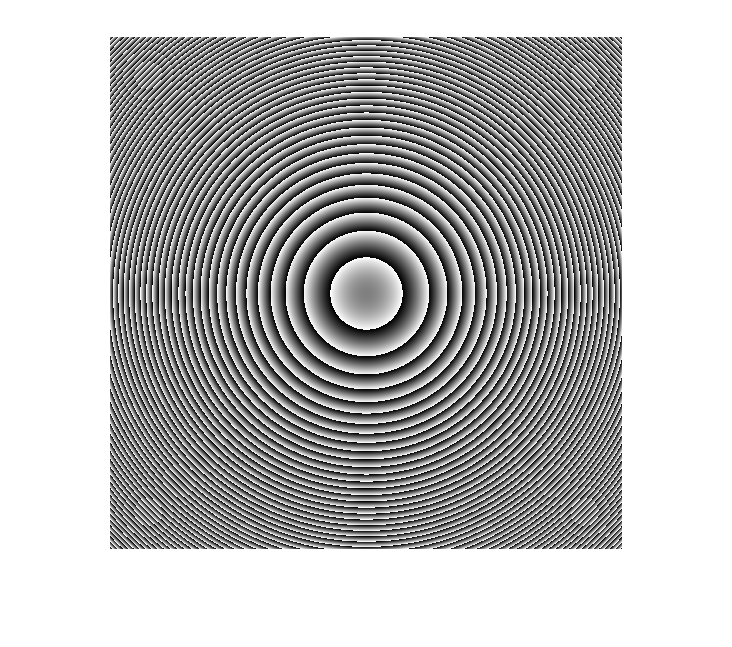

% Input parameters
L_box = 128e-6;
D_box = L_box / 16;
N_box = 512;
lbd = 500e-9;
y_box = linspace(-L_box/2, L_box/2, N_box);
x_box = y_box;
[x_box, y_box] = meshgrid(x_box, y_box);

%U_box = ((x_box).^2 <= (D_box / 2).^2) .* ((y_box).^2 <= (D_box / 2).^2) .*(exp(1i * 2 * pi / lbd * y_box * sin(20/ 360 * 2 * pi)));
U_box = ((x_box).^2 <= (D_box / 2).^2).* ((y_box).^2 <= (D_box / 2).^2);
M_box = 100;
z_box = M_box / N_box / lbd * L_box^2 * 2;
%z_box=0.0005;
rate=L_box/N_box;
[U_prop, Q] = scalable_angular_spectrum(U_box, z_box, lbd, L_box);
F = transform(U_box, 10*L_box, lbd, z_box, [rate, rate]);
% Display results
figure;
imagesc(angle(U_box));
colormap(hsv);
colorbar;
title('Input Phase');

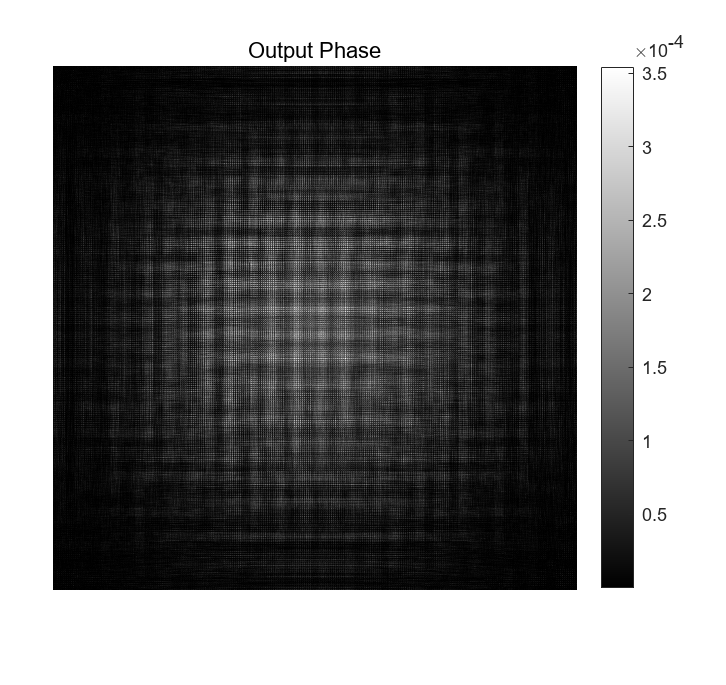


figure;
imshow(abs(F).^2,[]);
%colormap(hsv);
colorbar;
title('Output Phase');

function [psi_final, Q] = scalable_angular_spectrum(psi, z, lbd, L)
    % Returns the complex electrical field psi propagated with the Scalable Angular Spectrum Method.

    % Pad array
    pad_factor = 2;
    L_new = pad_factor * L;
    N_new = pad_factor * size(psi, 2);
    psi_p = zeros(N_new, N_new);
    as1 = floor((size(psi, 1) + 1) / 2);
    as2 = floor((size(psi, 2) + 1) / 2);
    psi_p(as1:as1 + size(psi, 2) - 1,as2:as2 + size(psi, 2) - 1) = psi;

    % Helper variables
    k = 2 * pi / lbd;
    df = 1 / L_new;
    Lf = N_new * df;
    f_y = fftshift(-(0:N_new-1) / (2 * Lf), 2);
    f_x = fftshift(-(0:N_new-1) / (2 * Lf), 2);
    y = linspace(-L_new/2, L_new/2, N_new);
    x = y;
    [f_x, f_y] = meshgrid(f_x, f_y);
    [x, y] = meshgrid(x, y);
    cx = lbd * f_x;
    cy = lbd * f_y;
    tx = L_new / 2 / z + abs(lbd * f_x);
    ty = L_new / 2 / z + abs(lbd * f_y);
    W = ((cx.^2 .* (1 + tx.^2) ./ tx.^2 + cy.^2) <= 1) & ((cy.^2 .* (1 + ty.^2) ./ ty.^2 + cx.^2) <= 1);

    % Calculate kernels
    H_AS = sqrt(0 + 1 - abs(f_x * lbd).^2 - abs(f_y * lbd).^2);
    H_Fr = 1 - abs(f_x * lbd).^2 / 2 - abs(f_y * lbd).^2 / 2;
    delta_H = W .* exp(1i * k * z * (H_AS - H_Fr));

    % Apply precompensation
    psi_precomp = ifft2(fft2(ifftshift(psi_p)) .* delta_H);

    % Output coordinates
    dq = lbd * z / L_new;
    Q = dq * size(psi, 3) * pad_factor;
    q_y = linspace(-Q/2, Q/2, N_new);
    q_x = q_y;
    [q_x, q_y] = meshgrid(q_x, q_y);

    H_1 = exp(1i * k / (2 * z) * (x.^2 + y.^2));

    % Final phase factor
    H_2 = exp(1i * k * z) * exp(1i * k / (2 * z) * (q_x.^2 + q_y.^2));
    psi_p_final = fftshift(fft2(H_1 .* psi_precomp)) .* H_2;

    % Strip off padding
    psi_final = psi_p_final(as1:as1 + size(psi, 1) - 1,as2:as2 + size(psi, 2) - 1);
end